# Predict Behaviour from Ca2+ signal using Machine learning

To see whether the information contained in the dendritic tree is able to predict the current behavioural state of the animal, we can try to use classification or regression between the Ca2+ signal and some behavioural metrics.

## Predictors

The approach requires some predictors, which, in our case are obtained from the GCaMP signal obtained from different part of the dendritic tree. We can use either the entire dendritic tree, or a subset of ROIs from the dendritic tree, or the average between different groups of ROIs (obtained, for example from a previous clustering analysis)

## Predictors preprocessing

Predictors correspond to Ca2+ signal. However, a number of preprocessing steps can be used:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use obj.rescaled_traces (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Observations

If we want to predict the behaviour from the Ca2+, we can use obj.behaviours. Classifiers require a binnarization step, while regression do not

# 1. Load experiment

Here we will directly use the existing arboreal_scan_object. For more advanced use cases, see Demo_FINAL_SERIES_OF_ANALYSIS

## 1.1 Use the default script to load the object

%% See script to change the default values across the demo scripts
STANDARD_INITIALIZATION()

	INFO : No change detected in time smoothing


lag_list =    -44   -42   -40   -38   -35   -33   -31   -29   -27   -24   -22   -20   -18   -15   -13   -11    -9    -7    -4    -2     0     2     4     7     9    11    13    15    18    20    22    24    27    29    31    33    35    38    40    42    44


lag_smoothing = 0


% Get a shorter list of behaviours to go faster
behaviours                          = {'encoder','BodyCam_L_whisker','trigger'};


# 2. Define the Analysis Settings

## Initialize metrics / regenerate them

	INFO : All plots were deleted


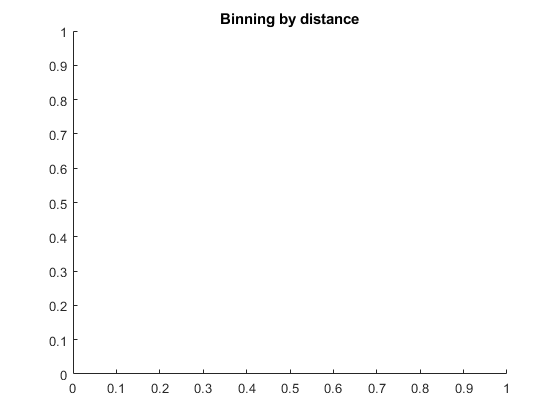

	INFO : obj.binned_data.median traces were computed using raw signals
	INFO : Bins were created. obj.binned_data is now available including group medians
	INFO : Now detecting events with tree-wide pairwise correlation at least > 0.2 %
	INFO : 	Events detection is using PAIRWISE CORRELATION between all provided traces
			Epochs of correlated changes of activity across > 20 %% of the tree/pop will be considered as an event
			Events > 50 %% correlation will be considered as "global events". smaler correlations are local events

	WARNING : 	Maximal tree correlation is 94.2766%%. A values < 100%% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
				This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes t

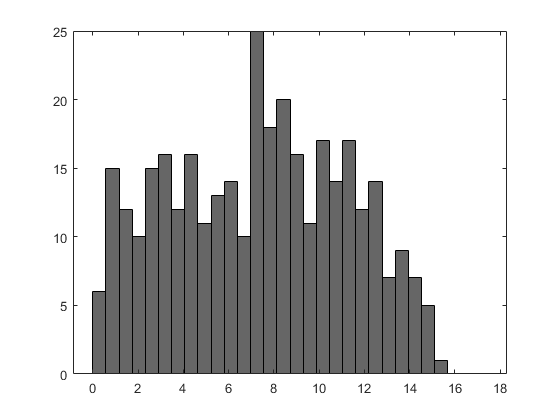

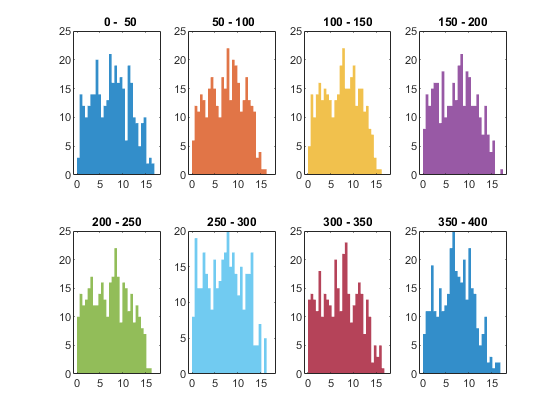

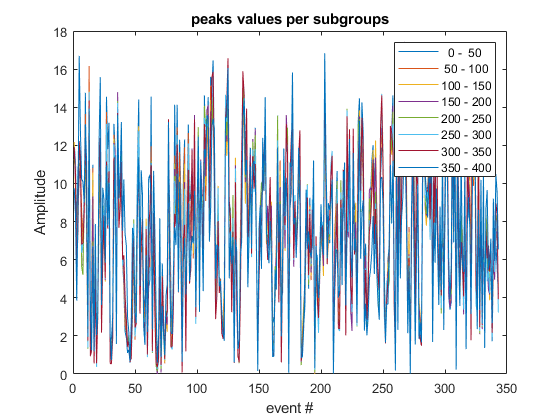

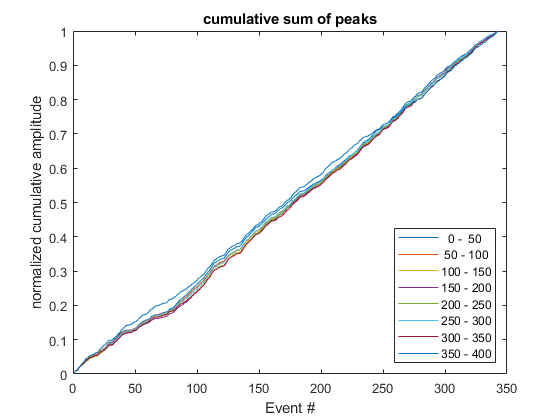

	INFO : Detected events statistics computed. See obj.binned_data for the group-specific values
	INFO : Event variability statistics have been computed using binned data. See obj.variability


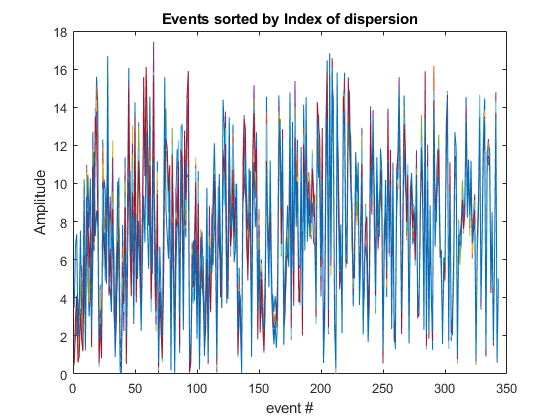

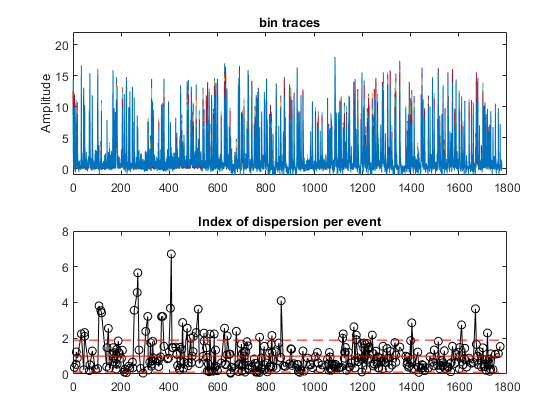

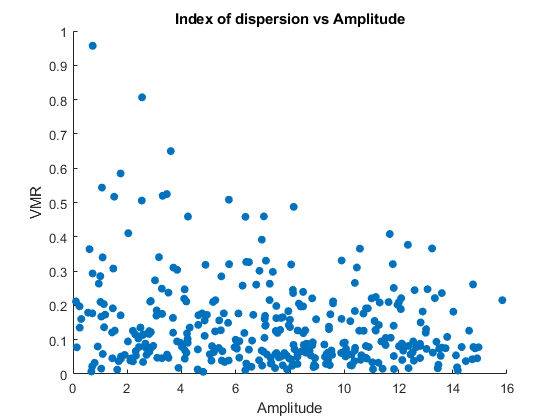

	INFO : General variability statistics have been computed. See obj.variability
	INFO : Current obj.cc_mode is : 
	INFO : Current obj.crosscorr_ref is : Qw|
	INFO : Correlation done between all valid ROIs, 
	Reference trace is the perisomatic averaged signal, at the indicated timpoints. 
	Correlation done using all timepoints, 
	INFO : Correlation based on 
	WARNING : n_components was not specified. Number of factors was estimated as the number of PCA components required to explain 90 % of the variance (3) components)
Doing PCA
PCA using random SVD
PCA took 0.0019763 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 161
First iteration: k = 100
Number of samples below the threshold from 1st iter: 161
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.0031251 seconds
Make kernel row stochastic
Running PHATE without landmarking
Fi

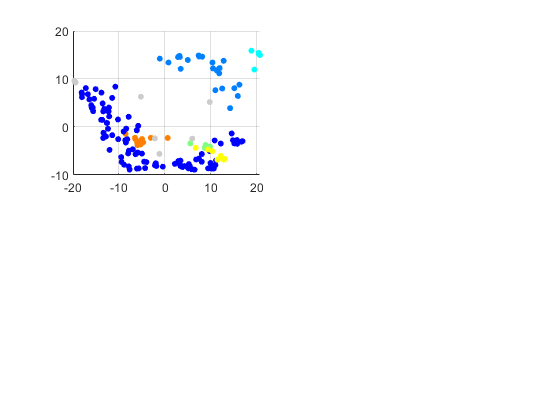

	INFO : Cluster number is sorted by number of ROI
	INFO : 	Clustering of dimensionality-reduced data done using dbscan
			6 clusters have been identified



obj.process({'distance',50});       % will use obj.time_smoothing and obj.rendering

## Machine Learning settings

ml_parameters = machine_learning_params(); % We'll start with the default options everywhere, and update them on demand

# 3. Run a simple linear regression model

## 3.1.1 Run a simple linear regression model once, on all 3 behaviours, with all ROIs using the peaks amplitude

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1


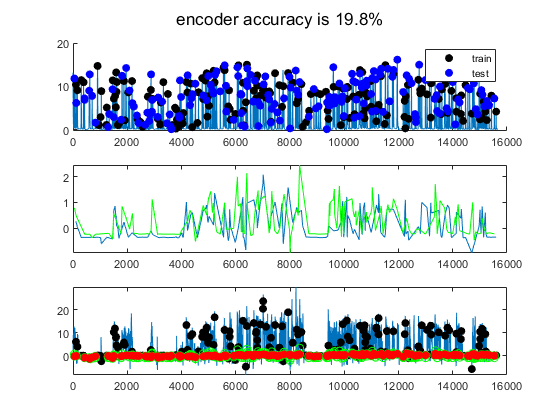

p = 1; Conditions do not significantly differ from each other


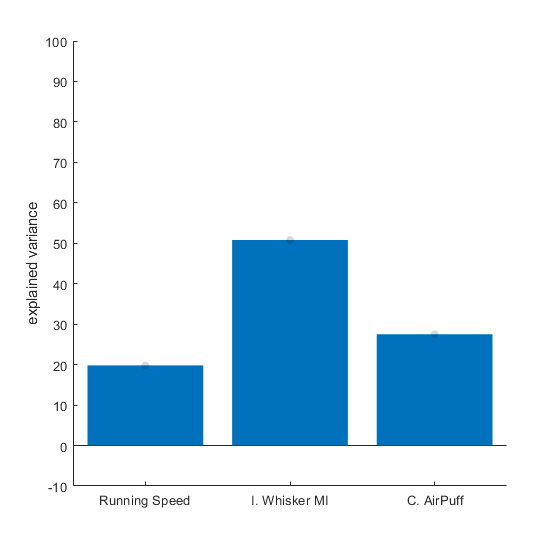

results             = predict_behaviours(obj,'peaks'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

%% From now on, we'll only plot the final result
ml_parameters.rendering = 1;

## 3.1.2 Run a simple linear regression model once, on all 3 behaviours, with all ROIs using the peaks modulation

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
p = 1; Conditions do not significantly differ from each other


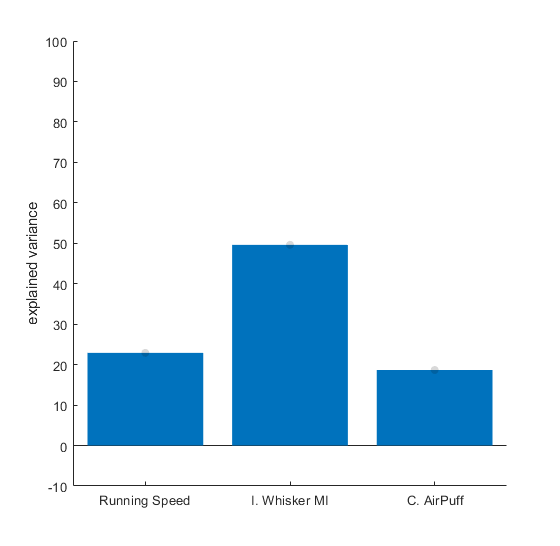

results             = predict_behaviours(obj,'peaks_subtracted' ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

## 3.2 Same as above, running the model 10 times

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
Iteration : 6
Iteration : 7
Iteration : 8
Iteration : 9
Iteration : 10
some conditions are significantly different from others


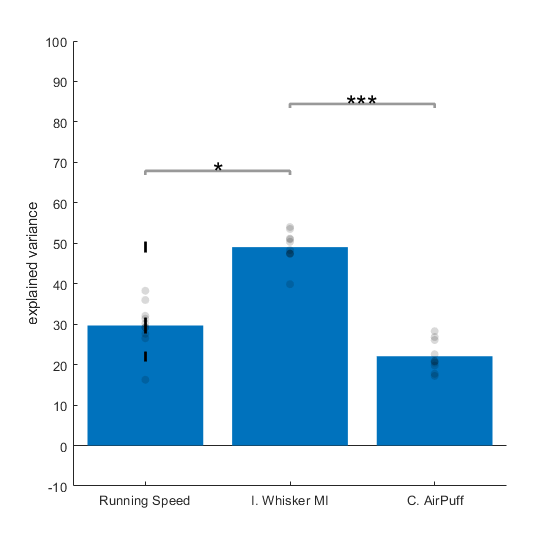

%% Increasing the number of repetition will enable statistical testing
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'N_iter',10);     % see defaults at the top); 


%% From now on, we'll do 10 iteration every time
ml_parameters.N_iter = 10;

## 3.3.1 Same as above, but doing hyperparameter optimization, using the native matlab method

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
Iteration : 6
Iteration : 7
Iteration : 8
Iteration : 9
Iteration : 10
some conditions are significantly different from others


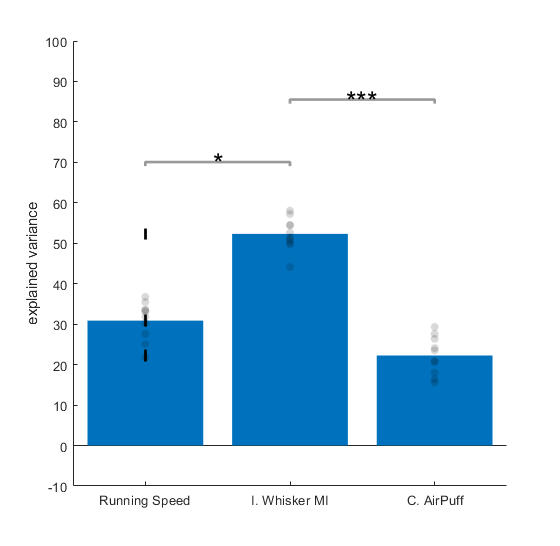

%% Hyperparameter optimization will improve the performances for each iteration of the model
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'optimize_hyper', true);     % see defaults at the top);  


%% From now on, we'll always do hyperparemters optimization
ml_parameters.optimize_hyper = true;


## 3.3.1 Same as above, but doing hyperparameter optimization, using the native matlab method

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1
Iteration : 2
Iteration : 3
Iteration : 4
Iteration : 5
Iteration : 6
Iteration : 7
Iteration : 8
Iteration : 9
Iteration : 10
some conditions are significantly different from others


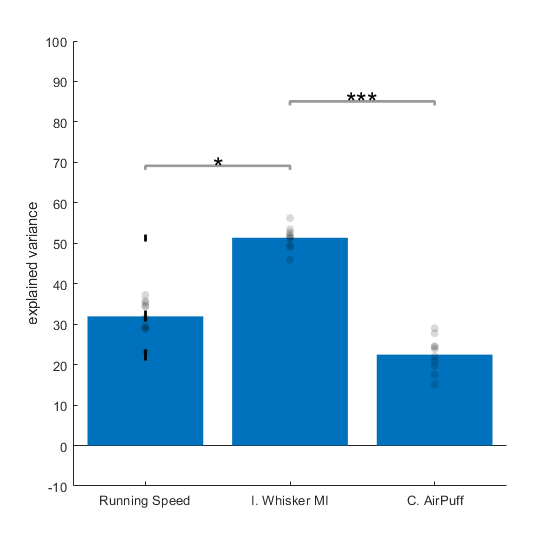

%% Manual Hyperparameter optimization is faster than the native method
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'optimization_method', 'manual');     % see defaults at the top);  


%% From now on, we'll always do hyperparemters optimization
ml_parameters.optimization_method = 'manual';

# 4. Run a simple svm regression model

## 4.1 Run a svm regression model 10 times, on all 3 behaviours, with all ROIs using the peaks modulation

%% Increasing the number of repetition will enable statistical testing
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'method', 'svm');    % svm model. This has its own hyperparameter optimization routine

	INFO : obj.binned_data.median traces were computed using rescaled signals
Iteration : 1


Error using prediction>svm_hyperparameters_optimization (line 341)
to fix with the new flexible scioring method

Error in prediction (line 46)
        [bmax, kmax] = svm_hyperparameters_optimization(x_train, y_train, x_test, y_test, cost, func, base_varargin, ml_parameters);   

Error in 

# 5. Run a classifier

## 5.1 Example : SVM classifier on all behaviours

% This is the default case : svm classifier
results             = predict_behaviours(obj,'peaks_subtracted'        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             []             ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters,...
                                             'method', 'svm', 'use_classifier', 'true');     % see defaults at the top);  